## PART 1: KINEMATICS

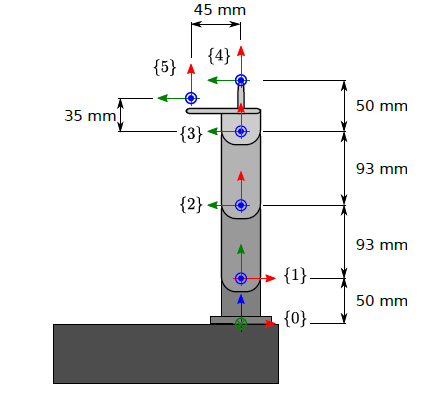

addpath('./src');

### Problem 1:

Find, by the use of Figure 1, the direct kinematic transformations, $$T_{4}^{0}$$ for the robot stylus, and $$T_{5}^{0}$$ for the robot camera, as function of all joint angles.

% Preliminary transformations

L01 = 50;
L12 = 93;
L23 = 93;
L34 = 50;
L45 = 45;
L35 = 35;

% % Uncomment for symbolic representation
syms theta0 theta1 theta2 theta3 

% from DH convention we get:

% {0} -> {1}
T01 = [cos(theta0), 0, sin(theta0), 0;
       sin(theta0), 0, -cos(theta0), 0;
       0, 1, 0, L01;
       0, 0, 0, 1];

% {1} -> {2}
T12 = [cos(theta1), -sin(theta1), 0, L12*sin(theta1);
       sin(theta1), cos(theta1), 0, L12*sin(theta1);
       0, 0, 1, 0;
       0, 0, 0, 1];

% {2} -> {3}
T23 = [cos(theta2), -sin(theta2), 0, L23*sin(theta2);
       sin(theta2), cos(theta2), 0, L23*sin(theta2);
       0, 0, 1, 0;
       0, 0, 0, 1];

% {3} -> {4}     
T34 = [cos(theta3), -sin(theta3), 0, L34*sin(theta3);
       sin(theta3), cos(theta3), 0, L34*sin(theta3);
       0, 0, 1, 0;
       0, 0, 0, 1];

% {3} -> {5}
T35 = [1, 0, 0, L35;
       0, 1, 0, L45;
       0, 0, 1, 0;
       0, 0, 0, 1];

% Transformation from {0} to {4}
T04 = simplify(T01*T12*T23*T34)

$$T04 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2}\,\cos\left(\theta_{0}\right) & -\sigma_{1}\,\cos\left(\theta_{0}\right) & \sin\left(\theta_{0}\right) & -\cos\left(\theta_{0}\right)\,\sigma_{3}\\ \sigma_{2}\,\sin\left(\theta_{0}\right) & -\sigma_{1}\,\sin\left(\theta_{0}\right) & -\cos\left(\theta_{0}\right) & -\sin\left(\theta_{0}\right)\,\sigma_{3}\\ \sigma_{1} & \sigma_{2} & 0 & 93\,\sin\left(\theta_{1}\right)+\sigma_{5}+\sigma_{4}+50\,\sin\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\right)+50\,\sin\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right)+50\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ \sigma_{2}=\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ \sigma_{3}=\sigma_{4}-\sigma_{5}-93\,\sin\left(\theta_{1}\right)+50\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)+50\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)+50\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)-50\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\\ \sigma_{4}=93\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ \sigma_{5}=93\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) \end{array}$$


% Transformation from {0} to {5}
T05 = simplify(T01*T12*T23*T35)

$$T05 = \begin{array}{l} \left(\begin{array}{cccc} \cos\left(\theta_{1}+\theta_{2}\right)\,\cos\left(\theta_{0}\right) & -\sin\left(\theta_{1}+\theta_{2}\right)\,\cos\left(\theta_{0}\right) & \sin\left(\theta_{0}\right) & \cos\left(\theta_{0}\right)\,\sigma_{1}\\ \cos\left(\theta_{1}+\theta_{2}\right)\,\sin\left(\theta_{0}\right) & -\sin\left(\theta_{1}+\theta_{2}\right)\,\sin\left(\theta_{0}\right) & -\cos\left(\theta_{0}\right) & \sin\left(\theta_{0}\right)\,\sigma_{1}\\ \sin\left(\theta_{1}+\theta_{2}\right) & \cos\left(\theta_{1}+\theta_{2}\right) & 0 & 93\,\sin\left(\theta_{1}\right)+45\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)+128\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+35\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)+48\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+50\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=93\,\sin\left(\theta_{1}\right)+35\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)+48\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-45\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)-128\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) \end{array}$$

### Problem 2: 

Determine the inverse kinematic transformation


$$$q = [q_1, q_2, q_3, q_4]^T = f(x_{4}^0, o_{4}^0)$$$


where $$x_{4}^{0}$$ are the first 3 components of the first column of $$T_{4}^{0}$$ , and $$o_{4}^{0}$$ are the first 3 components of the last column of $$T_{4}^{0}$$ , respectively. Satisfy all position components in $$o_{4}^{0}$$ and as many components in $$x_{4}^{0}$$ as possible.

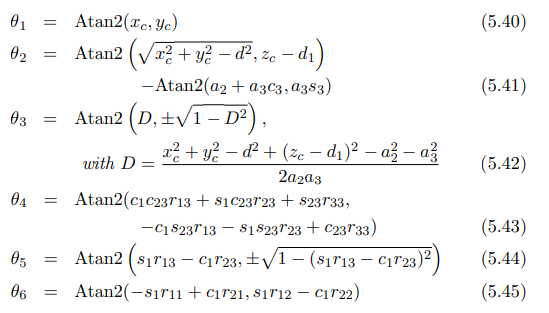

xc = 100;
yc = 100;
zc = 100;


d = L12; % or 23
D = (xc^2 + yc^2 - d^2 + (zc - L01)^2 - L12^2 - L23^2)/(2*L12*L23)

D = -0.1993


% create r

R01 = [1 0 0 0;
       0 cos(theta0) -sin(theta0) 0;
       0 sin(theta0) cos(theta0) 0;
       0 0 0 1];
% {1} -> {2}
R12 = [cos(theta1) -sin(theta1) 0 0;
       sin(theta1) cos(theta1) 0 0;
       0 0 1 0;
       0 0 0 1];

R = R01*R12;



theta0 = atan2(xc,yc);

theta2 = atan2(D, sqrt(1-D^2));

theta1 = atan2(sqrt(xc^2 + yc^2 - d^2) , zc - L01) - atan2(L12+L23*cos(theta3), L23*sin(theta3));

R01 = [1 0 0 0;
       0 cos(theta0) -sin(theta0) 0;
       0 sin(theta0) cos(theta0) 0;
       0 0 0 1];
% {1} -> {2}
R12 = [cos(theta1) -sin(theta1) 0 0;
       sin(theta1) cos(theta1) 0 0;
       0 0 1 0;
       0 0 0 1];

R = R01*R12;





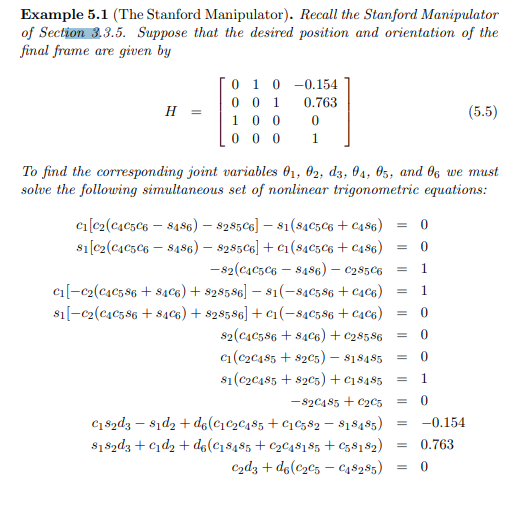

Next up we need to set up and solve this mess of equations.

We have the equations for T04 in the original matrixes calculated from the symbolic variables and we can derive the absolute value of H from the theta values calculated from the grapically derived equations.

## **Problem 3:**

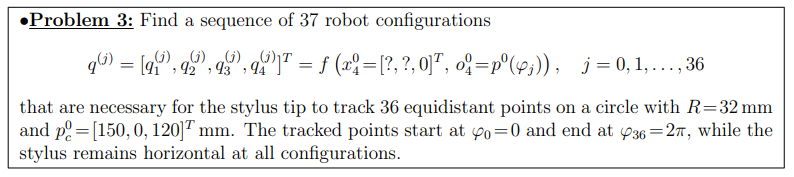

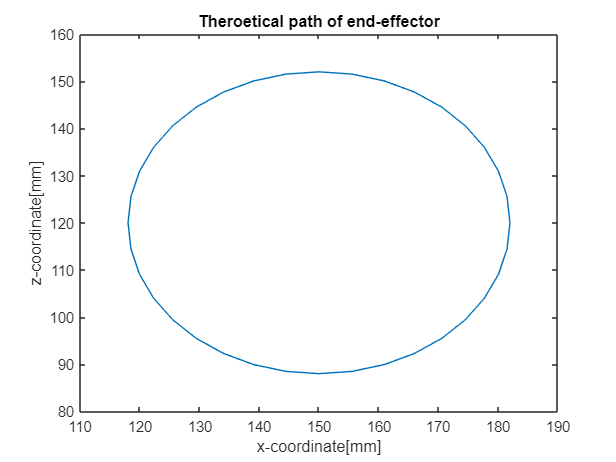


% origin of the circle to be traced
xc = 150;
yc = 0;
zc = 120;

radius = 32; %mm

angles = 0:2*pi/36:2*pi; % this is the phi angle reported in the previous line


dx = cos(angles)*radius;
dz = sin(angles)*radius;

x = xc + dx;
y = yc*ones(1,length(angles));
z = zc + dz;

figure
plot(x,z)
title("Theroetical path of end-effector")
xlabel("x-coordinate[mm]")
ylabel("z-coordinate[mm]")



% transform coordinates to angles
% Stylus always parallel to the ground
x04 = [0, 0, 1];
pos = [x; y; z];

for p = 1:size(pos,2)
    [t1(p),t2(p),t3(p),t4(p)] = invKinematics(x04, pos(:,p));
end


%t4 = ones(1,length(x)).*(pi-t1-t2-t3) % ensures horizontality

% R01 = [1 0 0 0;
%        0 cos(t1) -sin(t1) 0;
%        0 sin(t1) cos(t1) 0;
%        0 0 0 1];
% % {1} -> {2}
% R12 = [cos(t2) -sin(t2) 0 0;
%        sin(t2) cos(t2) 0 0;
%        0 0 1 0;
%        0 0 0 1];
% 
% R = R01*R12;
% 
% 
% t4 =atan2(cos(t1).*cos(t2+t3).*R(1,3) + sin(t1).*cos(t2+t3).*R(2,3) + sin(t2+t3).*R(3,3), -cos(t1).*sin(t2+t3).*R(1,3) - sin(t1).*sin(t2+t3).*R(2,3)+cos(t2+t3).*R(3,3));


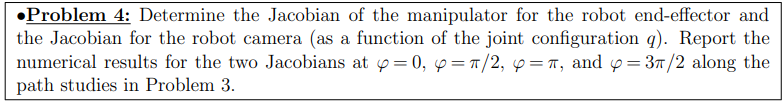




phi = [0 pi/2 pi 3*pi/2];


dy = cos(phi)*radius;
dz = sin(phi)*radius;

x = xc*ones(1,length(phi))

x =    150   150   150   150


y = yc + dy

y =    32.0000    0.0000  -32.0000   -0.0000


z = zc + dz

z =    120   152   120    88



% Taras can you help use the coordinates here to help

x04 = [0, 0, 1];
pos = [x; y; z];

t41 = ones(length(x),1);
t42 = ones(length(x),1);
t43 = ones(length(x),1);
t44 = ones(length(x),1);


for i = 1:length(x)

    [t41(i),t42(i),t43(i),t4(i)] = invKinematics(x04, pos(:,i));

    [T01, T12, T23, T34, T35] = T_finder(t41(i),t42(i),t43(i),t44(i));
    J = Jacob(T01, T12, T23, T34)
end

J =    -1.4603 -102.6616  -11.8433   57.8572
    6.8450  -21.9011   -2.5266   12.3429
         0    6.9990  -85.8629   -6.3695
         0    0.2086    0.2086    0.2086
         0   -0.9780   -0.9780   -0.9780
    1.0000         0         0         0


J =    -0.0000  -64.5463   22.2259   45.2220
   73.5797   -0.0000    0.0000    0.0000
         0   73.5797  -13.1925   38.6696
         0    0.0000    0.0000    0.0000
         0   -1.0000   -1.0000   -1.0000
    1.0000         0         0         0


J =     1.4603 -102.6616  -11.8433   57.8572
    6.8450   21.9011    2.5266  -12.3429
         0    6.9990  -85.8629   -6.3695
         0   -0.2086   -0.2086   -0.2086
         0   -0.9780   -0.9780   -0.9780
    1.0000         0         0         0


J =    -0.0000 -141.3340  -49.8464   50.0411
   -9.7471    0.0000    0.0000   -0.0000
         0   -9.7471 -101.2347  -32.1909
         0   -0.0000   -0.0000   -0.0000
         0   -1.0000   -1.0000   -1.0000
    1.0000         0         0         0


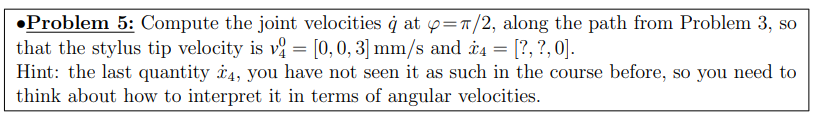

%[T01_old, T12_old, T23_old, T34_old, T35_old] = T_finder(t1(1),t2(1),t3(1),t4(1));

for i = 2:length(t1)
    disp(i)
    disp(t1(i))
    disp(t2(i))
    disp(t3(i))
    disp(t4(i))
    
    [T01, T12, T23, T34, T35] = T_finder(t1(i),t2(i),t3(i),t4(i));

    T04=T01*T12*T23*T34;
    T03=T01*T12*T23;
    T02=T01*T12;
    
    o4 = [T04(1,4) T04(2,4) T04(3,4)];

    dt1 = t1(i) - t1(i-1);
    dt2 = t2(i) - t2(i-1);
    dt3 = t3(i) - t3(i-1);
    dt4 = t4(i) - t4(i-1);


    % want to normalize the vector lenth
    k1 = [T01(1,4); T01(2,4); T01(3,4)];
    k1 = k1/norm(k1);
    k2 = [T12(1,4); T12(2,4); T12(3,4)];
    k2 = k2/norm(k2);
    k3 = [T23(1,4); T23(2,4); T23(3,4)];
    k3 = k3/norm(k3);
    k4 = [T34(1,4); T34(2,4); T34(3,4)];
    k4 = k4/norm(k4);

    w01 = dt1*k1;
    w12 = dt2*k2;
    w23 = dt3*k3;
    w34 = dt4*k4;

    R01 = [T01(1,1) T01(1,2) T01(1,3);T01(2,1) T01(2,2) T01(2,3);T01(3,1) T01(3,2) T01(3,3)];
    R02 = [T02(1,1) T02(1,2) T02(1,3);T02(2,1) T02(2,2) T02(2,3);T02(3,1) T02(3,2) T02(3,3)];
    R03 = [T03(1,1) T03(1,2) T03(1,3);T03(2,1) T03(2,2) T03(2,3);T03(3,1) T03(3,2) T03(3,3)];
    R04 = [T04(1,1) T04(1,2) T04(1,3);T04(2,1) T04(2,2) T04(2,3);T04(3,1) T04(3,2) T04(3,3)];

    w04 = w01 + R01*w12 + R02*w23 + R03*w34

    v04 = cross(w04,o4)
    




end

     2



    0.7829



   -0.9144



   60.0129



  -57.5277



w04 =     7.0472
    7.0115
    1.7912


v04 =    23.3832  -23.5022         0


     3



    0.7752



    0.1828



   55.8735



  -54.4855



w04 =     4.3101
    4.2235
    5.0573


v04 =   -33.4990   34.1862   -0.0000


     4



    0.7626



    1.0332



   51.2510



  -50.7133



w04 =     3.8281
    3.6571
   -5.1422


v04 = 	1.0e+03 *

    1.1174   -1.1697         0


     5



    0.7448



    1.7196



   46.3092



  -46.4580



w04 =     2.9054
    2.6788
    1.7550


v04 =   637.1856 -691.0795    0.0000


     6



    0.7222



   -0.7827



   41.2803



  -38.9268



w04 =    10.2086
    8.9930
    4.9835


v04 =   317.0152 -359.8645   -0.0000


     7



    0.6947



   -0.0280



   36.4888



  -34.8900



w04 =     5.0532
    4.2110
    0.9642


v04 =  -154.9905  185.9885    0.0000


     8



    0.6628



    1.0665



   32.3825



  -31.8782



w04 =     3.7593
    2.9347
   -4.1594


v04 = 	1.0e+03 *

    0.8696   -1.1139    0.0000


     9



    0.6270



   -0.3551



   29.5320



  -27.6061



w04 =     2.5077
    1.8170
    6.4013


v04 =   584.1302 -806.1979    0.0000


    10



    0.5880



   -0.8707



   28.4985



  -26.0569



w04 =     2.4367
    1.6245
    0.4518


v04 =    -6.4714    9.7071    0.0000


    11



    0.5469



   -0.3551



   29.5320



  -27.6061



w04 =    -0.9591
   -0.5839
   -2.3753


v04 =  -191.9801  315.3501    0.0000


    12



    0.5049



    1.0665



   32.3825



  -31.8782



w04 =    -3.3579
   -1.8558
    5.0584


v04 = 	1.0e+03 *

   -0.6172    1.1168         0


    13



    0.4636



   -0.0280



   36.4888



  -34.8900



w04 =    -4.3987
   -2.1994
   -0.7704


v04 =    79.3716 -158.7432   -0.0000


    14



    0.4249



   -0.7827



   41.2803



  -38.9268



w04 =    -7.2034
   -3.2588
   -1.2456


v04 =   -73.1191  161.6234   -0.0000


    15



    0.3902



    1.7196



   46.3092



  -46.4580



w04 =    -1.2730
   -0.5236
   -2.7532


v04 =  -116.5465  283.3484   -0.0000


    16



    0.3614



    1.0332



   51.2510



  -50.7133



w04 =    -5.3434
   -2.0198
    5.6860


v04 = 	1.0e+03 *

   -0.6211    1.6432   -0.0000


    17



    0.3397



    0.1828



   55.8735



  -54.4855



w04 =    -6.4422
   -2.2769
   -5.5211


v04 =    16.0099  -45.2978   -0.0000


    18



    0.3263



   -0.9144



   60.0129



  -57.5277



w04 =    -5.9813
   -2.0241
    0.7093


v04 =    27.2577  -80.5495    0.0000


    19



    0.3218



    0.8279



   63.5604



  -62.8176



w04 =     4.5231
    1.5077
    0.9782


v04 =   291.8405 -875.5216    0.0000


    20



    0.3263



   -0.9035



   66.4582



  -63.9838



w04 =    -2.5973
   -0.8789
    1.1524


v04 =    20.7524  -61.3256   -0.0000


    21



    0.3397



    0.1688



   68.6971



  -67.2951



w04 =    -3.1895
   -1.1273
   -2.7467


v04 =   -24.3829   68.9883   -0.0000


    22



    0.3614



    0.9214



   70.3143



  -69.6649



w04 =    -1.8629
   -0.7042
    2.7091


v04 =  -256.2448  677.9115   -0.0000


    23



    0.3902



    1.3935



   71.3873



  -71.2099



w04 =    -0.6273
   -0.2580
   -0.2493


v04 =   -68.3165  166.0914    0.0000


    24



    0.4249



    1.6412



   72.0228



  -72.0932



w04 =     0.1913
    0.0865
   -0.0914


v04 =    17.2686  -38.1708         0


    25



    0.4636



   -1.4101



   72.3427



  -69.3618



w04 =     3.7949
    1.8974
    0.9824


v04 =   -45.7260   91.4519         0


    26



    0.5049



   -1.4088



   72.4671



  -69.4875



w04 =    -0.1900
   -0.1050
    0.1633


v04 =    10.9368  -19.7894         0


    27



    0.5469



   -1.4358



   72.4966



  -69.4900



w04 = 3×1
   -0.0057
   -0.0035
    0.0800


v04 = 1×3
    3.9988   -6.5685   -0.0000


    28



    0.5880



   -1.4498



   72.4986



  -69.4781



w04 = 3×1
    0.0160
    0.0107
    0.0474


v04 = 1×3
    2.1219   -3.1829    0.0000


    29



    0.6270



   -1.4358



   72.4966



  -69.4900



w04 = 3×1
   -0.0156
   -0.0113
    0.0327


v04 = 1×3
    2.1684   -2.9928    0.0000


    30



    0.6628



   -1.4088



   72.4671



  -69.4875



w04 = 3×1
    0.0057
    0.0044
   -0.0016


v04 = 1×3
   -0.2474    0.3169    0.0000


    31



    0.6947



   -1.4101



   72.3427



  -69.3618



w04 = 3×1
    0.1611
    0.1343
   -0.1043


v04 = 1×3
  -11.6687   14.0024   -0.0000


    32



    0.7222



    1.6412



   72.0228



  -72.0932



w04 = 3×1
    2.9945
    2.6379
   -0.2446


v04 = 1×3
  464.1842 -526.9257    0.0000


    33



    0.7448



    1.3935



   71.3873



  -71.2099



w04 = 3×1
    0.3059
    0.2820
    0.1792


v04 = 1×3
   73.7824  -80.0230    0.0000


    34



    0.7626



    0.9214



   70.3143



  -69.6649



w04 = 3×1
    0.9501
    0.9077
   -1.7396


v04 = 1×3
  327.2247 -342.5211   -0.0000


    35



    0.7752



    0.1688



   68.6971



  -67.2951



w04 = 3×1
    1.7429
    1.7079
    2.0107


v04 = 1×3
   36.0420  -36.7814         0


    36



    0.7829



   -0.9035



   66.4582



  -63.9838



w04 = 3×1
    4.3050
    4.2832
    1.6888


v04 = 1×3
  119.0372 -119.6431         0


    37



    0.7854



    0.8279



   63.5604



  -62.8176



w04 = 3×1
    0.3781
    0.3781
   -0.8319


v04 = 1×3
  115.8497 -115.8497    0.0000


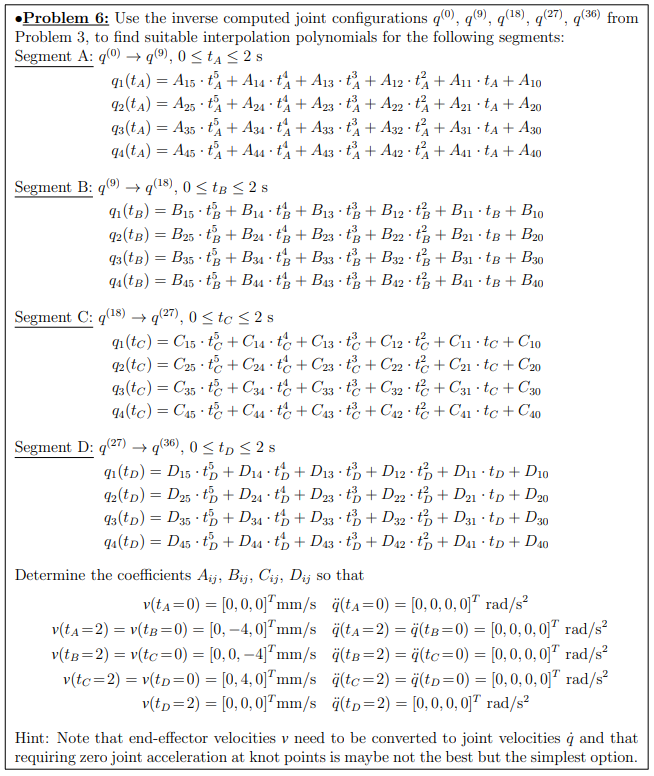

load("t1.mat");
load("t2.mat");
load("t3.mat");
load("t4.mat");
tIN = 0;%start point of each time interval
tOUT = 2;%end point of each time interval

V0 = [0;0;0;0;0;0];
VA = [0;-4;0;0;0;0];
VB = [0;0;-4;0;0;0];
VC = [0;4;0;0;0;0];
VD = [0;0;0;0;0;0];

q0 = [t1(1),t2(1),t3(1),t4(1)]';
qA = [t1(10),t2(10),t3(10),t4(10)]';
qB = [t1(19),t2(19),t3(19),t4(19)]';
qC = [t1(28),t2(28),t3(28),t4(28)]';
qD = [t1(37),t2(37),t3(37),t4(37)]';

%vectors of end-effffector velocities v 
[T01,T12,T23,T34,T35] = T_finder(t1(1),t2(1),t3(1),t4(1));
J0 = Jacob(T01,T12,T23,T34);

[T01,T12,T23,T34,T35] = T_finder(t1(10),t2(10),t3(10),t4(10));
JA = Jacob(T01,T12,T23,T34);

[T01,T12,T23,T34,T35] = T_finder(t1(19),t2(19),t3(19),t4(19));
JB = Jacob(T01,T12,T23,T34);

[T01,T12,T23,T34,T35] = T_finder(t1(28),t2(28),t3(28),t4(28));
JC = Jacob(T01,T12,T23,T34);

[T01,T12,T23,T34,T35] = T_finder(t1(37),t2(37),t3(37),t4(37));
JD = Jacob(T01,T12,T23,T34);

%jaconbian matrix for calculating joint velocities ˙q
q0_dot = [0, 0, 0, 0]';
qA_dot = JA'*inv(JA*JA')*VA;

qB_dot = JB'*inv(JB*JB')*VB;

qC_dot = JC'*inv(JC*JC')*VC;

qD_dot = JD'*inv(JD*JD')*VD;


%Calculation of joint velocities ˙q
ain = [0,0,0,0]';
aout = [0,0,0,0]';
%acceleration is always 0

A = getConstant(tIN,tOUT,q0,qA,q0_dot,qA_dot,ain,aout)

A = 6×4
    0.7854    0.8279   63.5604  -62.8176
   -0.0000         0    0.0000   -0.0000
         0         0         0         0
   -0.2624   -2.0608  -43.7571   45.8844
    0.1987    1.5378   32.8091  -34.4050
   -0.0399   -0.3068   -6.5609    6.8802


B = getConstant(tIN,tOUT,qA,qB,qA_dot,qB_dot,ain,aout)

B = 6×4
    0.5880   -0.8707   28.4985  -26.0569
    0.0156   -0.0625   -0.0703    0.0664
         0         0         0         0
   -0.3563    2.2731   43.8331  -46.0065
    0.2652   -1.7040  -32.8535   34.4911
   -0.0529    0.3407    6.5686   -6.8968


C = getConstant(tIN,tOUT,qB,qC,qB_dot,qC_dot,ain,aout)

C = 6×4
    0.3218    0.8279   63.5604  -62.8176
         0   -0.0560    0.0999   -0.0439
         0         0         0         0
    0.3641   -2.7319   11.0620   -8.3536
   -0.2770    2.0520   -8.3139    6.2824
    0.0558   -0.4107    1.6645   -1.2582


D = getConstant(tIN,tOUT,qC,qD,qC_dot,qD_dot,ain,aout)

D = 6×4
    0.5880   -1.4498   72.4986  -69.4781
   -0.0312   -0.0313   -0.0391    0.0938
         0         0         0         0
    0.2936    2.8940  -11.1142    8.1850
   -0.2163   -2.1666    8.3405   -6.1505
    0.0429    0.4329   -1.6686    1.2313



% The constant for Ani is A(n,i) where n is the joint number and i is the
% constant number



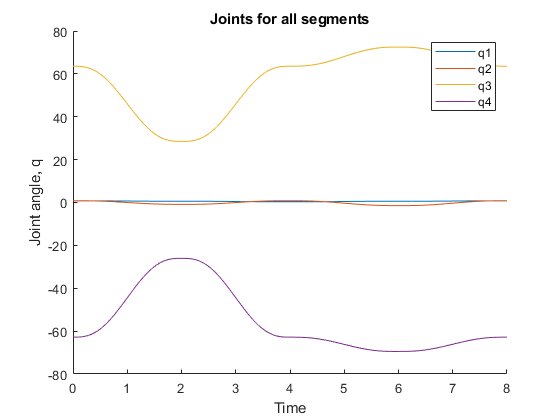

t = 0:0.01:2;
q1A = A(1,1) + A(2,1).*t + A(3,1).*t.^2 + A(4,1).*t.^3 + A(5,1).*t.^4 + A(6,1).*t.^5;
q2A = A(1,2) + A(2,2).*t + A(3,2).*t.^2 + A(4,2).*t.^3 + A(5,2).*t.^4 + A(6,2).*t.^5;
q3A = A(1,3) + A(2,3).*t + A(3,3).*t.^2 + A(4,3).*t.^3 + A(5,3).*t.^4 + A(6,3).*t.^5;
q4A = A(1,4) + A(2,4).*t + A(3,4).*t.^2 + A(4,4).*t.^3 + A(5,4).*t.^4 + A(6,4).*t.^5;

q1B = B(1,1) + B(2,1).*t + B(3,1).*t.^2 + B(4,1).*t.^3 + B(5,1).*t.^4 + B(6,1).*t.^5;
q2B = B(1,2) + B(2,2).*t + B(3,2).*t.^2 + B(4,2).*t.^3 + B(5,2).*t.^4 + B(6,2).*t.^5;
q3B = B(1,3) + B(2,3).*t + B(3,3).*t.^2 + B(4,3).*t.^3 + B(5,3).*t.^4 + B(6,3).*t.^5;
q4B = B(1,4) + B(2,4).*t + B(3,4).*t.^2 + B(4,4).*t.^3 + B(5,4).*t.^4 + B(6,4).*t.^5;

q1C = C(1,1) + C(2,1).*t + C(3,1).*t.^2 + C(4,1).*t.^3 + C(5,1).*t.^4 + C(6,1).*t.^5;
q2C = C(1,2) + C(2,2).*t + C(3,2).*t.^2 + C(4,2).*t.^3 + C(5,2).*t.^4 + C(6,2).*t.^5;
q3C = C(1,3) + C(2,3).*t + C(3,3).*t.^2 + C(4,3).*t.^3 + C(5,3).*t.^4 + C(6,3).*t.^5;
q4C = C(1,4) + C(2,4).*t + C(3,4).*t.^2 + C(4,4).*t.^3 + C(5,4).*t.^4 + C(6,4).*t.^5;

q1D = D(1,1) + D(2,1).*t + D(3,1).*t.^2 + D(4,1).*t.^3 + D(5,1).*t.^4 + D(6,1).*t.^5;
q2D = D(1,2) + D(2,2).*t + D(3,2).*t.^2 + D(4,2).*t.^3 + D(5,2).*t.^4 + D(6,2).*t.^5;
q3D = D(1,3) + D(2,3).*t + D(3,3).*t.^2 + D(4,3).*t.^3 + D(5,3).*t.^4 + D(6,3).*t.^5;
q4D = D(1,4) + D(2,4).*t + D(3,4).*t.^2 + D(4,4).*t.^3 + D(5,4).*t.^4 + D(6,4).*t.^5;

% combine the joint angles 
q1 = [q1A, q1B(2:end), q1C(2:end), q1D(2:end)];
q2 = [q2A, q2B(2:end), q2C(2:end), q2D(2:end)];
q3 = [q3A, q3B(2:end), q3C(2:end), q3D(2:end)];
q4 = [q4A, q4B(2:end), q4C(2:end), q4D(2:end)];
t_all = 0:0.01:8;

figure 
hold on
plot(t_all,q1)
plot(t_all,q2)
plot(t_all,q3)
plot(t_all,q4)
xlabel("Time")
ylabel("Joint angle, q")
title("Joints for all segments")
legend(["q1","q2","q3","q4"])

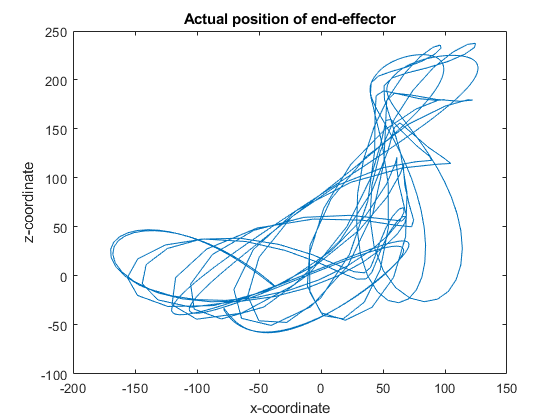



pos = zeros(4,length(q1));
for i = 1:length(pos)
    [T01, T12, T23, T34, T35] = T_finder(q1(i),q2(i),q3(i),q4(i));
    T04 = T01*T12*T23*T34;
    pos(:,i) = T04*[0,0,0,1]'; 
end

figure
plot(pos(1,:),pos(3,:))
title("Actual position of end-effector")
xlabel("x-coordinate")
ylabel("z-coordinate")

%%seven knot points
A71 = getConstant7(tIN,tOUT,MatrixofQ(1,1),MatrixofQ(1,2),v0,vA(1,1),ain,aout);

Unrecognized function or variable 'MatrixofQ'.

A72 = getConstant7(tIN,tOUT,MatrixofQ(2,1),MatrixofQ(2,2),v0,vA(1,1),ain,aout);
A73 = getConstant7(tIN,tOUT,MatrixofQ(3,1),MatrixofQ(3,2),v0,vA(1,1),ain,aout);
A74 = getConstant7(tIN,tOUT,MatrixofQ(4,1),MatrixofQ(4,2),v0,vA(1,1),ain,aout);
A7 = [A71 A72 A73 A74];
 
B71 = getConstant7(tIN,tOUT,MatrixofQ(1,2),MatrixofQ(1,3),vA(1,1),vB(2,1),ain,aout);
B72 = getConstant7(tIN,tOUT,MatrixofQ(2,2),MatrixofQ(2,3),vA(1,1),vB(2,1),ain,aout);
B73 = getConstant7(tIN,tOUT,MatrixofQ(3,2),MatrixofQ(3,3),vA(1,1),vB(2,1),ain,aout);
B74 = getConstant7(tIN,tOUT,MatrixofQ(4,2),MatrixofQ(4,3),vA(1,1),vB(2,1),ain,aout);
B7 = [B71 B72 B73 B74];

C71 = getConstant7(tIN,tOUT,MatrixofQ(1,3),MatrixofQ(1,4),vB(2,1),vC(3,1),ain,aout);
C72 = getConstant7(tIN,tOUT,MatrixofQ(2,3),MatrixofQ(2,4),vB(2,1),vC(3,1),ain,aout);
C73 = getConstant7(tIN,tOUT,MatrixofQ(3,3),MatrixofQ(3,4),vB(2,1),vC(3,1),ain,aout);
C74 = getConstant7(tIN,tOUT,MatrixofQ(4,3),MatrixofQ(4,4),vB(2,1),vC(3,1),ain,aout);
C7 = [C71 C72 C73 C74];

D71 = getConstant7(tIN,tOUT,MatrixofQ(1,4),MatrixofQ(1,5),vC(3,1),vD(4,1),ain,aout);
D72 = getConstant7(tIN,tOUT,MatrixofQ(2,4),MatrixofQ(2,5),vC(3,1),vD(4,1),ain,aout);
D73 = getConstant7(tIN,tOUT,MatrixofQ(3,4),MatrixofQ(3,5),vC(3,1),vD(4,1),ain,aout);
D74 = getConstant7(tIN,tOUT,MatrixofQ(4,4),MatrixofQ(4,5),vC(3,1),vD(4,1),ain,aout);
D7 = [D71 D72 D73 D74];

x = 0:0.01:8;
q71A = A71(8) * x.^7 + A71(7) * x.^6 + A71(6) * x.^5 + A71(5) * x.^4 + A71(4) * x.^3 + A71(3) * x.^2 + A71(2) * x + A71(1);
q72A = A72(8) * x.^7 + A72(7) * x.^6 + A72(6) * x.^5 + A72(5) * x.^4 + A72(4) * x.^3 + A72(3) * x.^2 + A72(2) * x + A72(1);
q73A = A73(8) * x.^7 + A73(7) * x.^6 + A73(6) * x.^5 + A73(5) * x.^4 + A73(4) * x.^3 + A73(3) * x.^2 + A73(2) * x + A73(1);
q74A = A74(8) * x.^7 + A74(7) * x.^6 + A74(6) * x.^5 + A74(5) * x.^4 + A74(4) * x.^3 + A74(3) * x.^2 + A74(2) * x + A74(1);

q71B = B71(8) * x.^7 + B71(7) * x.^6 + B71(6) * x.^5 + B71(5) * x.^4 + B71(4) * x.^3 + B71(3) * x.^2 + B71(2) * x + B71(1);
q72B = B72(8) * x.^7 + B72(7) * x.^6 + B72(6) * x.^5 + B72(5) * x.^4 + B72(4) * x.^3 + B72(3) * x.^2 + B72(2) * x + B72(1);
q73B = B73(8) * x.^7 + B73(7) * x.^6 + B73(6) * x.^5 + B73(5) * x.^4 + B73(4) * x.^3 + B73(3) * x.^2 + B73(2) * x + B73(1);
q74B = B74(8) * x.^7 + B74(7) * x.^6 + B74(6) * x.^5 + B74(5) * x.^4 + B74(4) * x.^3 + B74(3) * x.^2 + B74(2) * x + B74(1);

q71C = C71(8) * x.^7 + C71(7) * x.^6 + C71(6) * x.^5 + C71(5) * x.^4 + C71(4) * x.^3 + C71(3) * x.^2 + C71(2) * x + C71(1);
q72C = C72(8) * x.^7 + C72(7) * x.^6 + C72(6) * x.^5 + C72(5) * x.^4 + C72(4) * x.^3 + C72(3) * x.^2 + C72(2) * x + C72(1);
q73C = C73(8) * x.^7 + C73(7) * x.^6 + C73(6) * x.^5 + C73(5) * x.^4 + C73(4) * x.^3 + C73(3) * x.^2 + C73(2) * x + C73(1);
q74C = C74(8) * x.^7 + C74(7) * x.^6 + C74(6) * x.^5 + C74(5) * x.^4 + C74(4) * x.^3 + C74(3) * x.^2 + C74(2) * x + C74(1);

q71D = D71(8) * x.^7 + D71(7) * x.^6 + D71(6) * x.^5 + D71(5) * x.^4 + D71(4) * x.^3 + D71(3) * x.^2 + D71(2) * x + D71(1);
q72D = D72(8) * x.^7 + D72(7) * x.^6 + D72(6) * x.^5 + D72(5) * x.^4 + D72(4) * x.^3 + D72(3) * x.^2 + D72(2) * x + D72(1);
q73D = D73(8) * x.^7 + D73(7) * x.^6 + D73(6) * x.^5 + D73(5) * x.^4 + D73(4) * x.^3 + D73(3) * x.^2 + D73(2) * x + D73(1);
q74D = D74(8) * x.^7 + D74(7) * x.^6 + D74(6) * x.^5 + D74(5) * x.^4 + D74(4) * x.^3 + D74(3) * x.^2 + D74(2) * x + D74(1);
figure; % Create a new figure window
y1 = q71A.*(x>=0&x<=2) + q71B.*(x>2&x<=4) + q71C.*(x>4&x<=6) + q71D.*(x>6&x<=8);
plot(x, y1, 'b');
hold on
y2 = q72A.*(x>=0&x<=2) + q72B.*(x>2&x<=4) + q72C.*(x>4&x<=6) + q72D.*(x>6&x<=8);
plot(x, y2, 'r');
hold on
y3 = q73A.*(x>=0&x<=2) + q73B.*(x>2&x<=4) + q73C.*(x>4&x<=6) + q73D.*(x>6&x<=8);
plot(x, y3, 'g');
hold on
y4 = q74A.*(x>=0&x<=2) + q74B.*(x>2&x<=4) + q74C.*(x>4&x<=6) + q74D.*(x>6&x<=8);
plot(x, y1, 'y'); 

%%three knot points
A31 = getConstant3(tIN,tOUT,MatrixofQ(1,1),MatrixofQ(1,2),v0,vA(1,1));
A32 = getConstant3(tIN,tOUT,MatrixofQ(2,1),MatrixofQ(2,2),v0,vA(1,1));
A33 = getConstant3(tIN,tOUT,MatrixofQ(3,1),MatrixofQ(3,2),v0,vA(1,1));
A34 = getConstant3(tIN,tOUT,MatrixofQ(4,1),MatrixofQ(4,2),v0,vA(1,1));
A3 = [A31 A32 A33 A34];
 
B31 = getConstant3(tIN,tOUT,MatrixofQ(1,2),MatrixofQ(1,3),vA(1,1),vB(2,1));
B32 = getConstant3(tIN,tOUT,MatrixofQ(2,2),MatrixofQ(2,3),vA(1,1),vB(2,1));
B33 = getConstant3(tIN,tOUT,MatrixofQ(3,2),MatrixofQ(3,3),vA(1,1),vB(2,1));
B34 = getConstant3(tIN,tOUT,MatrixofQ(4,2),MatrixofQ(4,3),vA(1,1),vB(2,1));
B3 = [B31 B32 B33 B34];

C31 = getConstant3(tIN,tOUT,MatrixofQ(1,3),MatrixofQ(1,4),vB(2,1),vC(3,1));
C32 = getConstant3(tIN,tOUT,MatrixofQ(2,3),MatrixofQ(2,4),vB(2,1),vC(3,1));
C33 = getConstant3(tIN,tOUT,MatrixofQ(3,3),MatrixofQ(3,4),vB(2,1),vC(3,1));
C34 = getConstant3(tIN,tOUT,MatrixofQ(4,3),MatrixofQ(4,4),vB(2,1),vC(3,1));
C3 = [C31 C32 C33 C34];

D31 = getConstant3(tIN,tOUT,MatrixofQ(1,4),MatrixofQ(1,5),vC(3,1),vD(4,1));
D32 = getConstant3(tIN,tOUT,MatrixofQ(2,4),MatrixofQ(2,5),vC(3,1),vD(4,1));
D33 = getConstant3(tIN,tOUT,MatrixofQ(3,4),MatrixofQ(3,5),vC(3,1),vD(4,1));
D34 = getConstant3(tIN,tOUT,MatrixofQ(4,4),MatrixofQ(4,5),vC(3,1),vD(4,1));
D3 = [D31 D32 D33 D34];

x = 0:0.01:8;
q31A = A31(4) * x.^3 + A31(3) * x.^2 + A31(2) * x + A31(1);
q32A = A32(4) * x.^3 + A32(3) * x.^2 + A32(2) * x + A32(1);
q33A = A33(4) * x.^3 + A33(3) * x.^2 + A33(2) * x + A33(1);
q34A = A34(4) * x.^3 + A34(3) * x.^2 + A34(2) * x + A34(1);

q31B = B31(4) * x.^3 + B31(3) * x.^2 + B31(2) * x + B31(1);
q32B = B32(4) * x.^3 + B32(3) * x.^2 + B32(2) * x + B32(1);
q33B = B33(4) * x.^3 + B33(3) * x.^2 + B33(2) * x + B33(1);
q34B = B34(4) * x.^3 + B34(3) * x.^2 + B34(2) * x + B34(1);

q31C = C31(4) * x.^3 + C31(3) * x.^2 + C31(2) * x + C31(1);
q32C = C32(4) * x.^3 + C32(3) * x.^2 + C32(2) * x + C32(1);
q33C = C33(4) * x.^3 + C33(3) * x.^2 + C33(2) * x + C33(1);
q34C = C34(4) * x.^3 + C34(3) * x.^2 + C34(2) * x + C34(1);

q31D = D31(4) * x.^3 + D31(3) * x.^2 + D31(2) * x + D31(1);
q32D = D32(4) * x.^3 + D32(3) * x.^2 + D32(2) * x + D32(1);
q33D = D33(4) * x.^3 + D33(3) * x.^2 + D33(2) * x + D33(1);
q34D = D34(4) * x.^3 + D34(3) * x.^2 + D34(2) * x + D34(1);
figure; % Create a new figure window
y1 = q31A.*(x>=0&x<=2) + q31B.*(x>2&x<=4) + q31C.*(x>4&x<=6) + q31D.*(x>6&x<=8);
plot(x, y1, 'b');
hold on
y2 = q32A.*(x>=0&x<=2) + q32B.*(x>2&x<=4) + q32C.*(x>4&x<=6) + q32D.*(x>6&x<=8);
plot(x, y2, 'r');
hold on
y3 = q33A.*(x>=0&x<=2) + q33B.*(x>2&x<=4) + q33C.*(x>4&x<=6) + q33D.*(x>6&x<=8);
plot(x, y3, 'g');
hold on
y4 = q34A.*(x>=0&x<=2) + q34B.*(x>2&x<=4) + q34C.*(x>4&x<=6) + q34D.*(x>6&x<=8);
plot(x, y1, 'y'); 

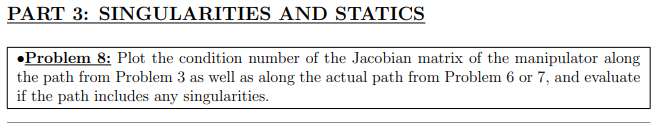


k=zeros(1,length(t1))
for i = 1:length(t1)
    [T01, T12, T23, T34, T35] = T_finder(t1(i),t2(i),t3(i),t4(i));
    J = Jacob(T01, T12, T23, T34); % Get jacobian at a given point
    J = [J(1:3,:);J(6,:)] ;% Remove rows that we do not wish to control
    k(i) = norm(inv(J))*norm(J); % calculate the condition number
end
figure;
plot(k,'.-')
xlabel('Joint configuration')
ylabel('Condition number')


% this uses the collection of angles from problem 3
len = length(t1);
torque2 = zeros(1,len);
torque3 = zeros(1,len);
torque4 = zeros(1,len);

for i=1:len
    [torque2(i),torque3(i),torque4(i)] = torques(t2(i),t3(i),t4(i),1);
end

figure
plot(t2,torque2)
hold on

plot(t3,torque3)

%plot(t4,torque4)

legend(["motor1", "motor2"])%,"motor3"])

disp("Motor 4 is omitted here as the torques are smaller than")